clear all; 

# Exercise 2.1 - Jacobian

In this exercise you will setup different function relating to the jacobian of a UR3e robot. 

Consider this UR3e robot and its dimensions. 

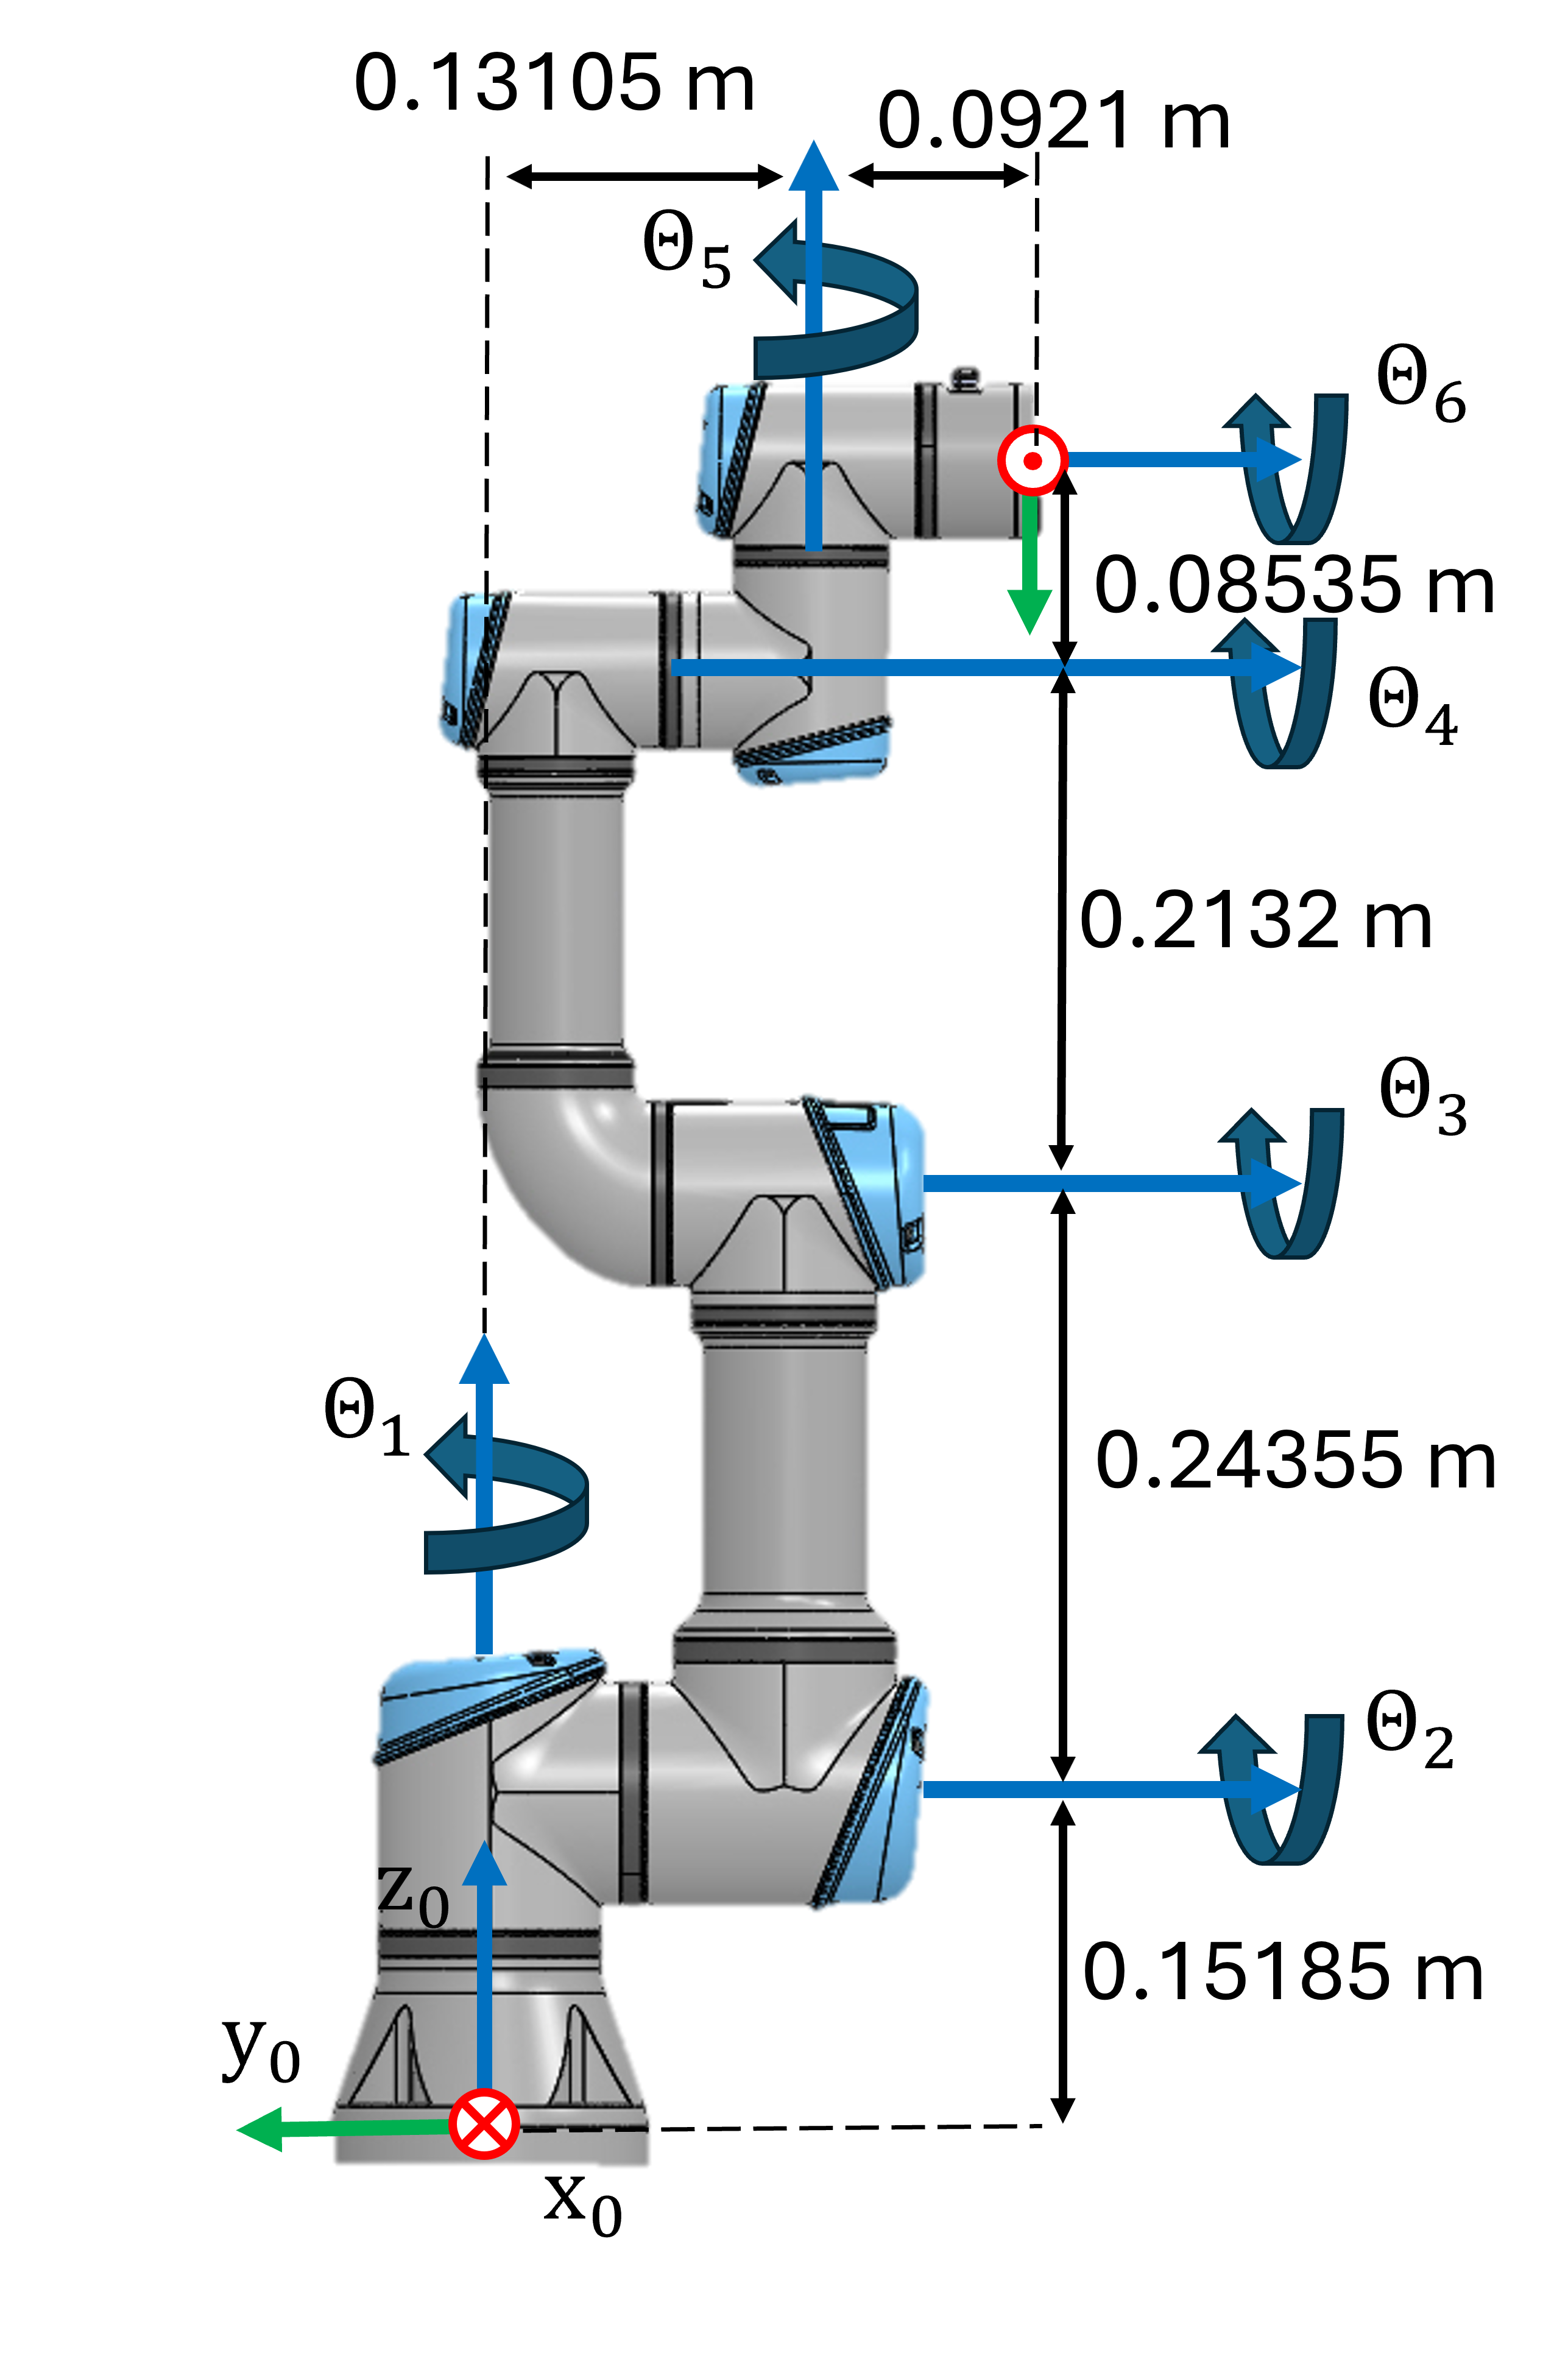

## Task 1

Setup the geometric Jacobian using the symbolic toolbox. The resulting symbolic expression should only depend on the joint states 

- Find the DH parameters and setup the Jacobian matrix. 

Use the following variables  to store your solution:

- q1 ... q6 (Real Symbolic variable for the Joint angle Theta 1-6)

- Jp (translational part of the Jacobian)

- Jtheta (rotational part of the Jacobian)

- J (complete Jacobian) 

Solve this exercise using the geometric approach! Use the function: 

- cross()

Solve this exercise without using the function: 

- dh2tf()

and without using the relation matrix $T_A \left(\Phi \right)$: 

- 
$$T_A \left(\Phi \right)=\left\lbrack \begin{array}{ccc}
0 & -\sin \left(\phi \right) & \cos \left(\phi \right)\cdot \sin \left(\theta \right)\\
0 & -\sin \left(\phi \right)\cdot \sin \left(\theta \right) & -\sin \left(\phi \right)\cdot \sin \left(\theta \right)\\
1 & \cos \left(\theta \right) & \cos \left(\theta \right)
\end{array}\right\rbrack$$


Jp = []; 
Jtheta = []; 
J = []; 

You can check your work by clicking the Run: 

 
check_exercise('3-1-1')

## Task 2

Write a function that computes the analytical jacobian (using euler angles) for a given configuration. This function takes one vector as an input: 

- configuration (q) as a row vector ($q\in {\mathbb{R}}^{6\mathrm{x1}}$)

and returns the analytical jacobian and its rank at the configuration.

Use the following function name for your solution:

-  ComputeAnalyticalJacobian(q)

Solve this exercise using an analytical approach! Use the function: 

- diff()

Solve this exercise without using the relation matrix $T_A \left(\Phi \right)$: 

- 
$$T_A \left(\Phi \right)=\left\lbrack \begin{array}{ccc}
0 & -\sin \left(\phi \right) & \cos \left(\phi \right)\cdot \sin \left(\theta \right)\\
0 & -\sin \left(\phi \right)\cdot \sin \left(\theta \right) & -\sin \left(\phi \right)\cdot \sin \left(\theta \right)\\
1 & \cos \left(\theta \right) & \cos \left(\theta \right)
\end{array}\right\rbrack$$


function [Ja, Rank] = ComputeAnalyticalJacobian(q)

Ja = []; 
Rank = []; 

end

You can check your work by clicking the Run: 

 
check_exercise('3-1-2')

## Task 3

Write a function that computes the required joint velocities to achieve a specific translational motion of the endeffector for a given configuration. This function takes two vector as an input: 

- configuration (q) as a row vector ($q\in {\mathbb{R}}^{6\textrm{x1}}$)

- desired motion v as a row vector where $v=\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} 
\end{array}\right\rbrack$

and returns the required joint speeds as a row vector ($\dot{q} \in {\mathbb{R}}^{6\mathrm{x1}}$).

Use the following function name for your solution:

-  ComputeJointSpeed(q,v)

Solve this exercise using an analytical approach! Use the function: 

- diff()

function qdot = ComputeJointSpeed(q,v)

qdot = []; 

end

You can check your work by clicking the Run: 

 
check_exercise('3-1-3')